## **Amplitude Modulation**

% Clear workspace and close figures
clear all;
close all;

% Load the audio file
audioFile = 'videoplayback.wav';
[x, fs] = audioread(audioFile);

% Play the audio file
disp('Playing the original audio...'); % Add a message to the console

Playing the original audio...


sound(x, fs); % Play the audio
pause(length(x) / fs); % Pause to allow time for audio playback (adjust the duration as needed)
disp('Audio playback completed.'); % Display a completion message

Audio playback completed.


% Split audio into left and right channels
l = x(:, 1); % Extract Left channel
r = x(:, 2); % Extract Right channel

% Create a time vector
t = (0:length(x) - 1) / fs;

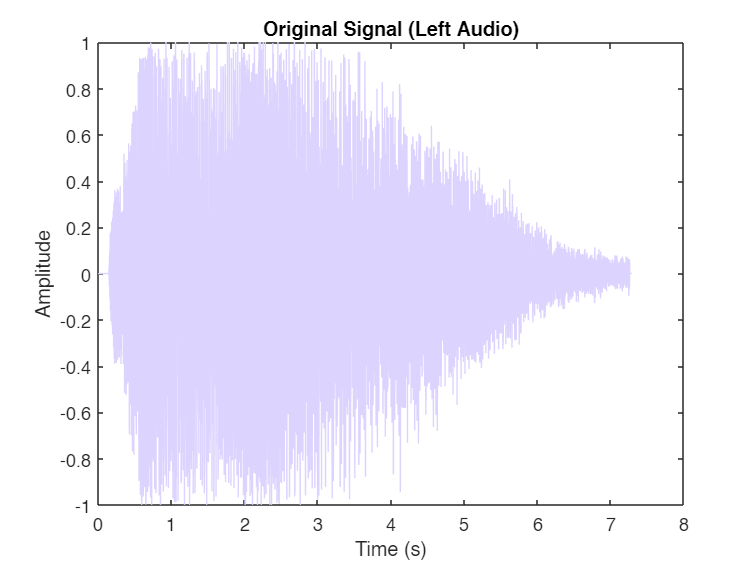

% Plot the original signal in the time domain (Left Audio)
figure;
plot(t, l, 'Color', '#dcd3ff');
title('Original Signal (Left Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

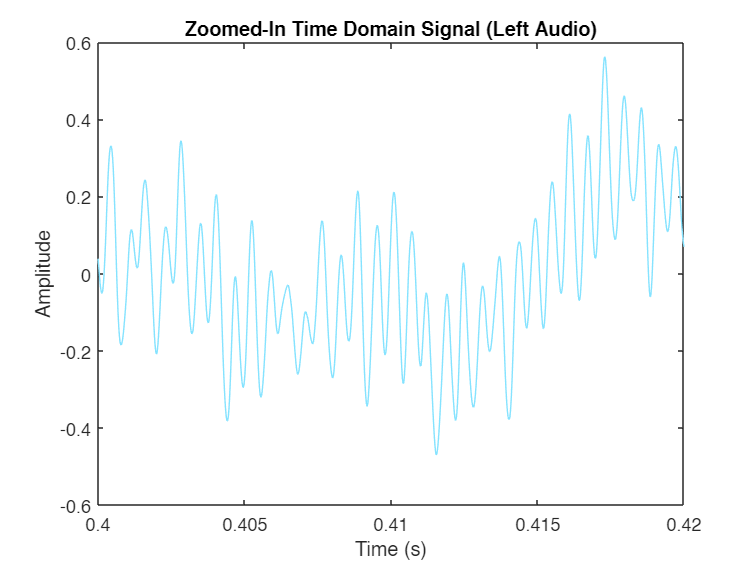

% Zoom in on a specific part of the time domain signal (Left Audio)
zoomStartTime = 0.4; % Start time for zoom (in seconds)
zoomEndTime = 0.42; % End time for zoom (in seconds)
zoomIdx = (t >= zoomStartTime) & (t <= zoomEndTime);

% Plot the zoomed in graph
figure;
plot(t(zoomIdx), l(zoomIdx), 'Color', '#85e3ff');
title('Zoomed-In Time Domain Signal (Left Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

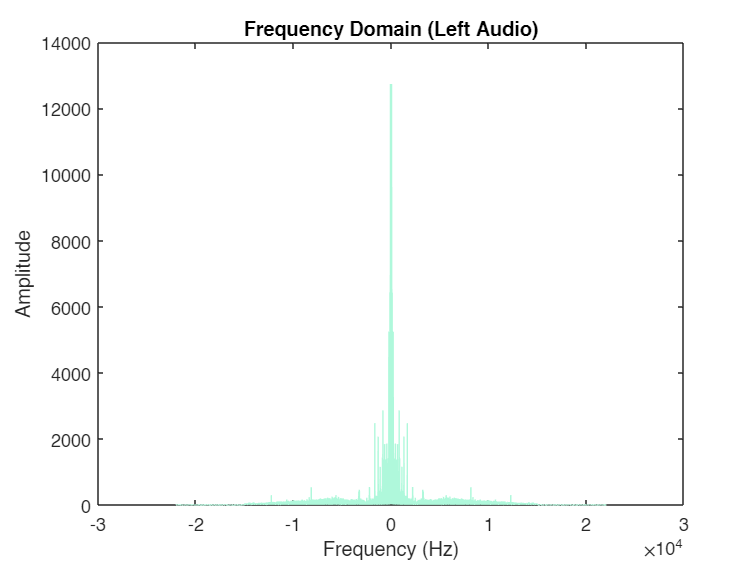

% Plot the original signal in the frequency domain (Left Audio)
L = fft(l);
f = (-length(L)/2:length(L)/2 - 1) * fs / length(L);

figure;
plot(f, abs(fftshift(L)), 'Color', '#aff8db');
title('Frequency Domain (Left Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

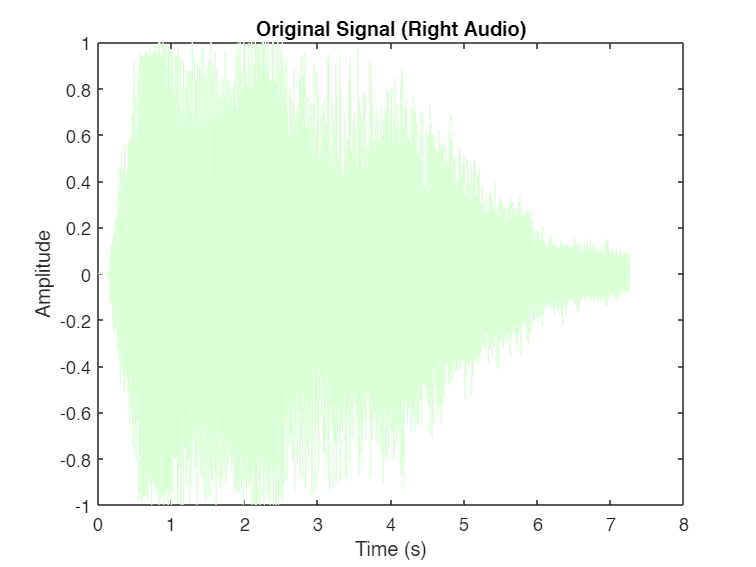

% Plot the original signal in the time domain (Right Audio)
figure;
plot(t, r, 'Color', '#dbffd6');
title('Original Signal (Right Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

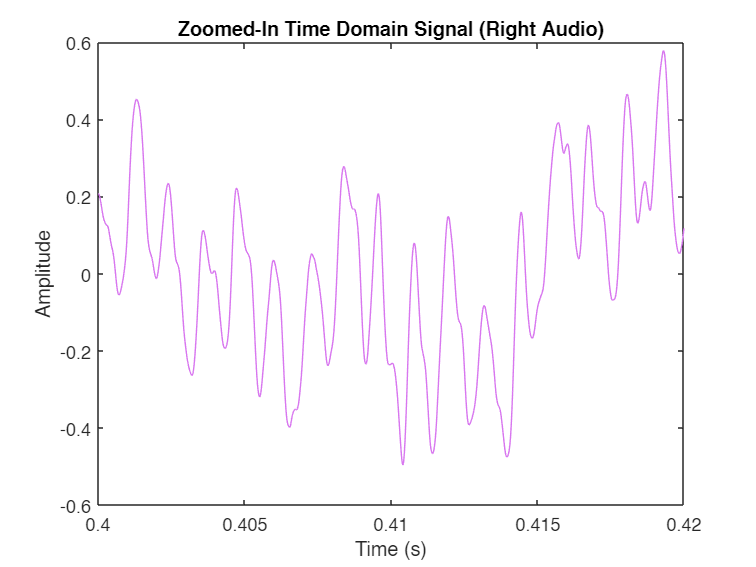

% Zoom in on a specific part of the time domain signal (Right Audio)
zoomIdx = (t >= zoomStartTime) & (t <= zoomEndTime);

% Plot
figure;
plot(t(zoomIdx), r(zoomIdx), 'Color', '#d877ef');
title('Zoomed-In Time Domain Signal (Right Audio)');
xlabel('Time (s)');
ylabel('Amplitude');

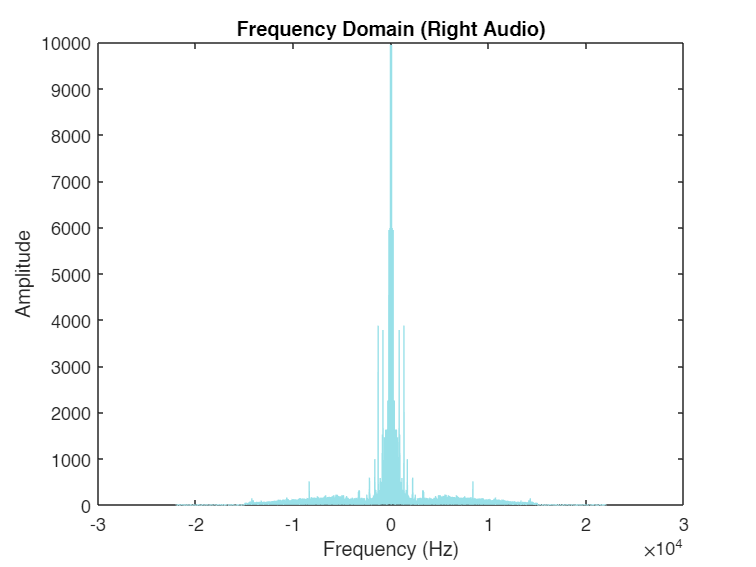

% Plot the original signal in the frequency domain (Right Audio)
R = fft(r);
f = (-length(R)/2:length(R)/2 - 1) * fs / length(R);

figure;
plot(f, abs(fftshift(R)), 'Color', '#98e0e8');
title('Frequency Domain (Right Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

% Defining new time windw for any further zooming in of signals
zoomStartTime = 0.4; % Start time for zoom (in seconds)
zoomEndTime = 0.4025; % End time for zoom (in seconds)

zoomIdx = (t >= zoomStartTime) & (t <= zoomEndTime);

% Modulation indices for under, critically, and over modulation
modulationIndices = [0.5, 1, 2];

% Defining the carrier frequency
fc = 1e6;

% Carrier Wave
c = 2 * cos(2 * pi * fc * t);

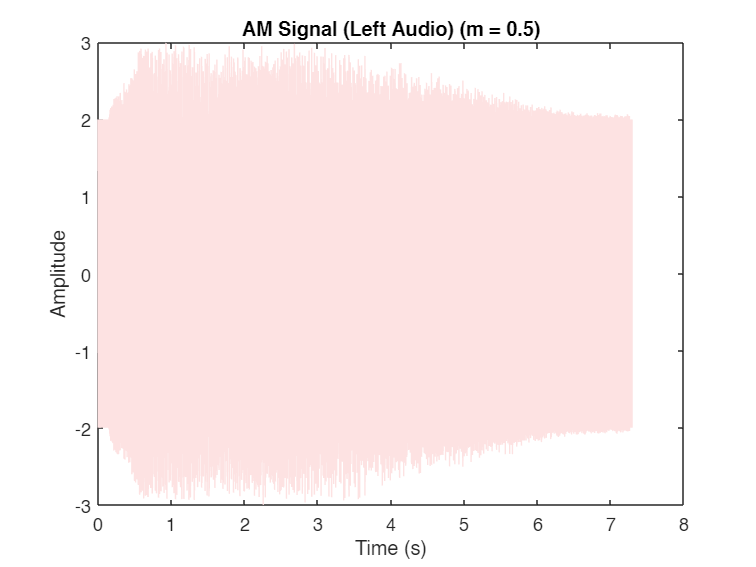

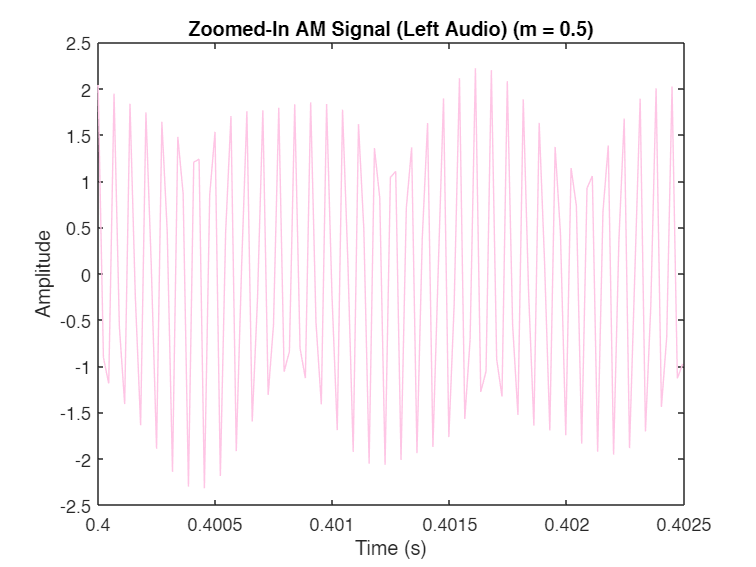

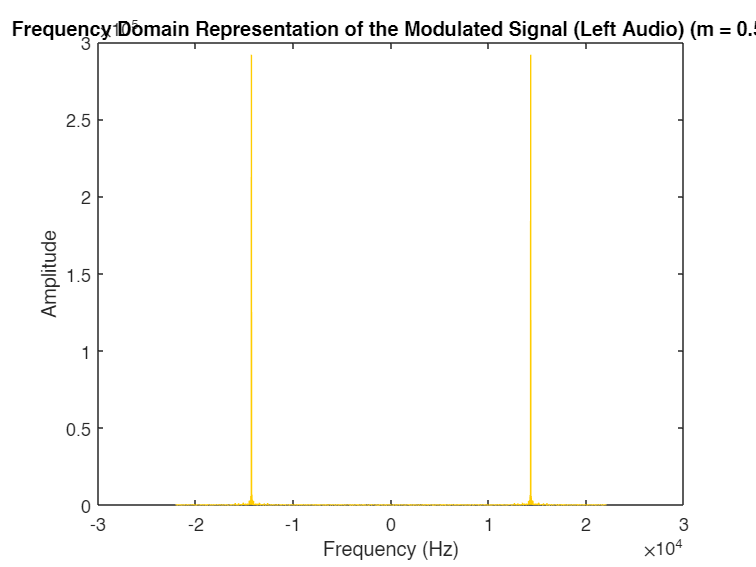

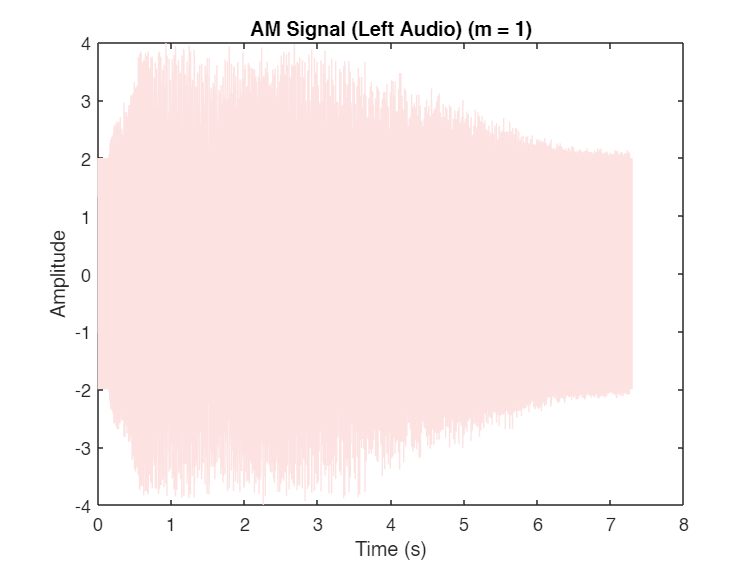

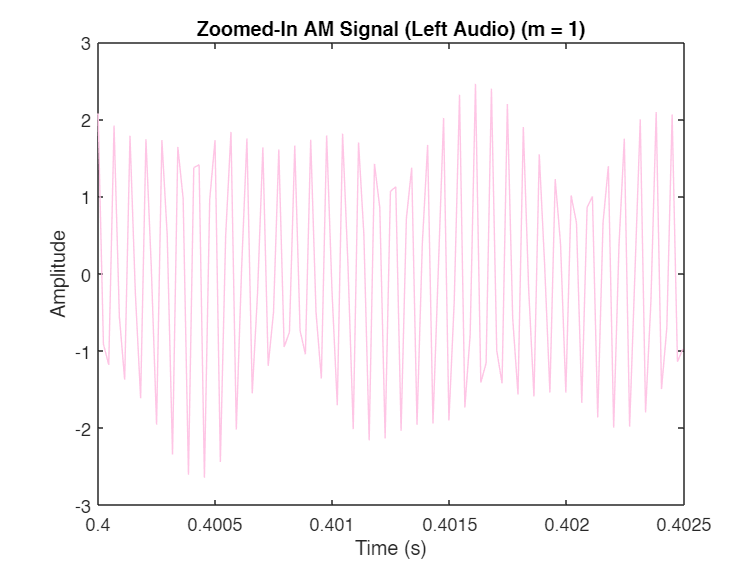

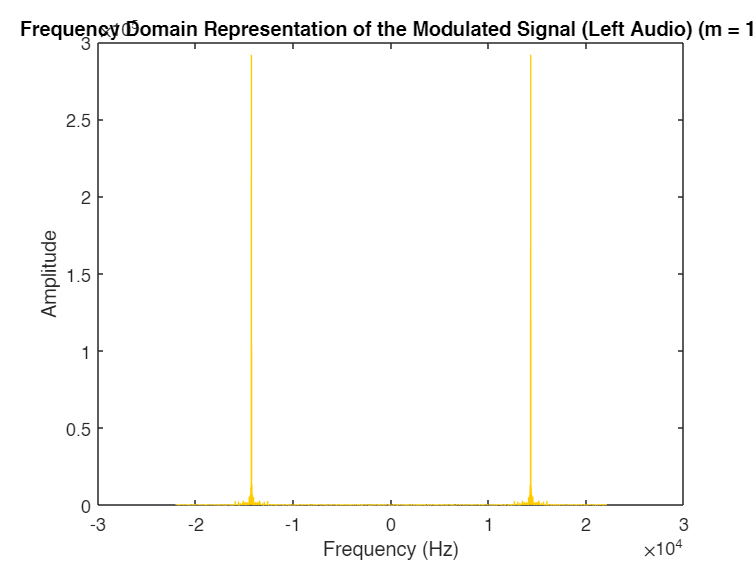

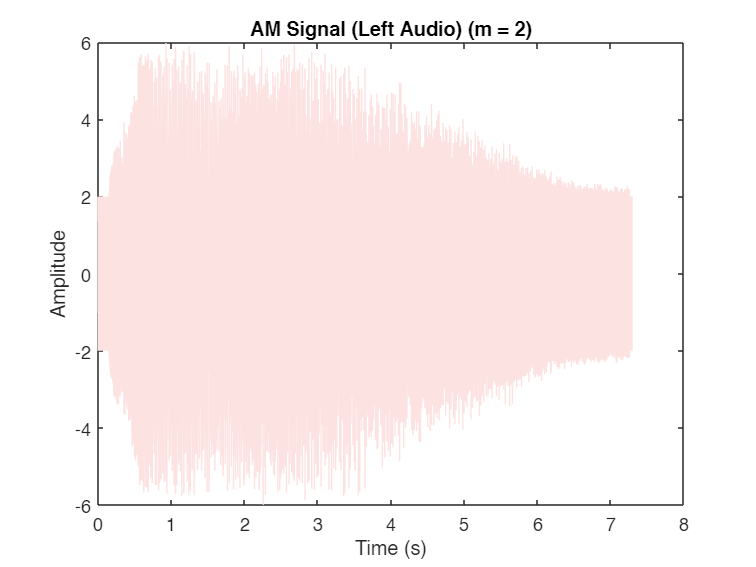

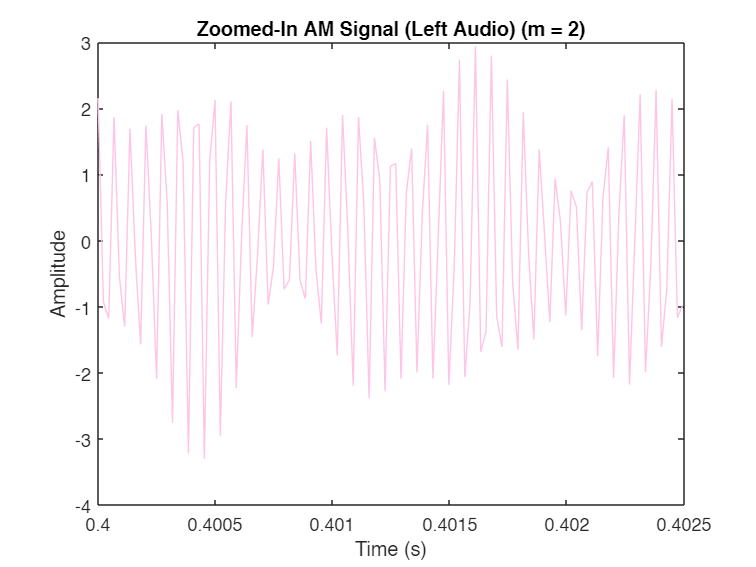

% Modulating left audio signal
l = reshape(l, size(c)); % Reshaping signal to match the shape of time vector

for i = 1:length(modulationIndices)
    % Generate the modulated signal with amplitude modulation (AM)
    m = modulationIndices(i); % Modulation index
    y = (1 + m * l) .* c; % AM modulation: Use .* for element-wise multiplication

    % Plot the modulated signal in the time domain
    figure;
    plot(t, y, 'Color', '#fde2e2');
    title(['AM Signal (Left Audio) (m = ', num2str(m), ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the zoomed-in AM signal
    figure;
    plot(t(zoomIdx), y(zoomIdx), 'Color', '#fec5e5');
    title(['Zoomed-In AM Signal (Left Audio) (m = ', num2str(m), ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the modulated signal in the frequency domain
    Y = fft(y);
    f = (-length(Y)/2:length(Y)/2 - 1) * fs / length(Y);
    
    figure;
    plot(f, abs(fftshift(Y)), 'Color','#ffcc00');
    title(['Frequency Domain Representation of the Modulated Signal (Left Audio) (m = ', num2str(m), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
end

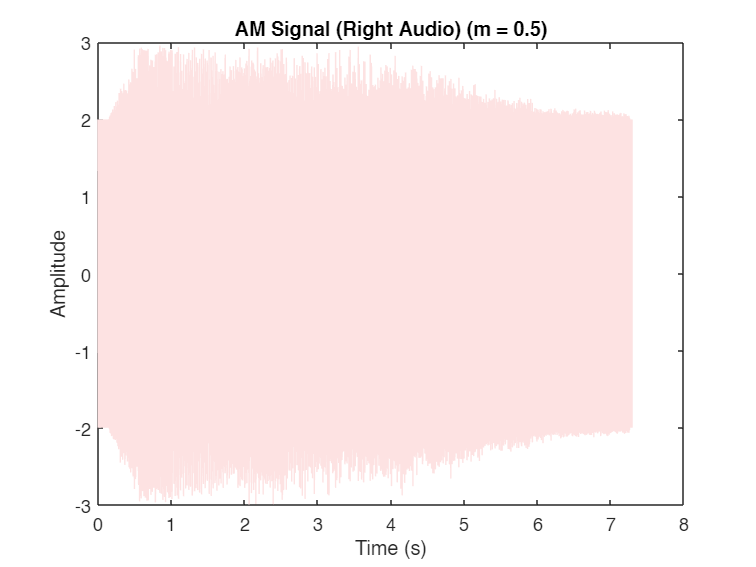

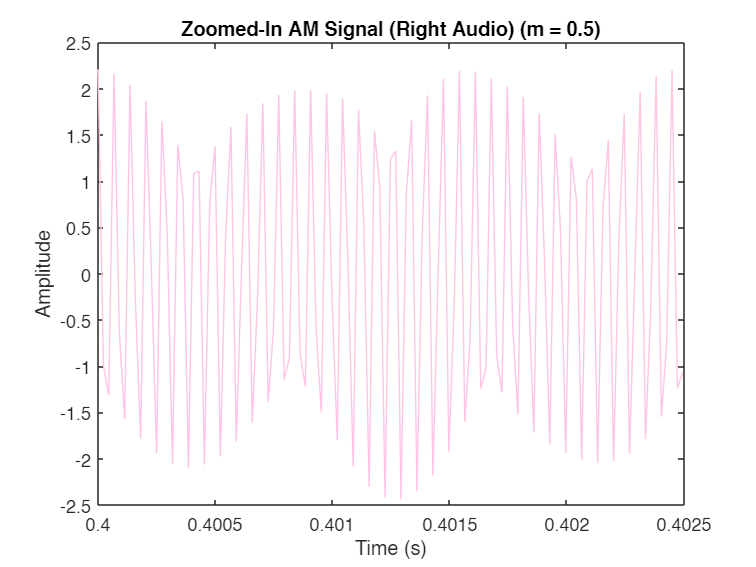

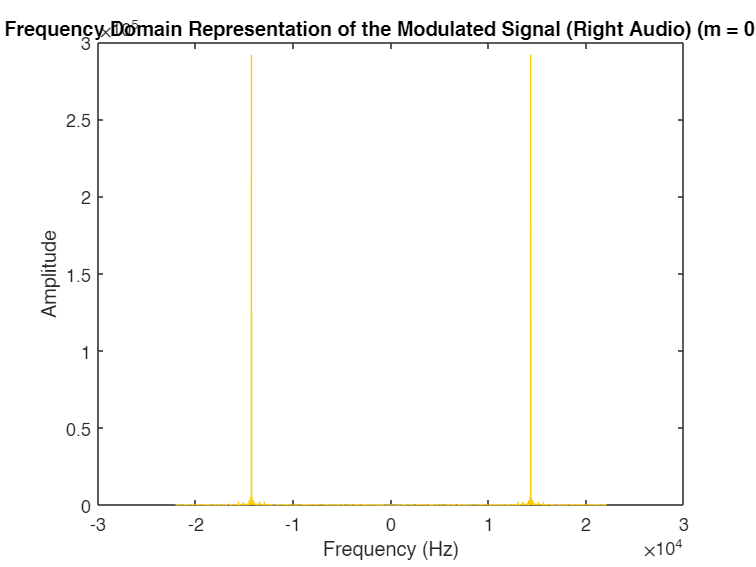

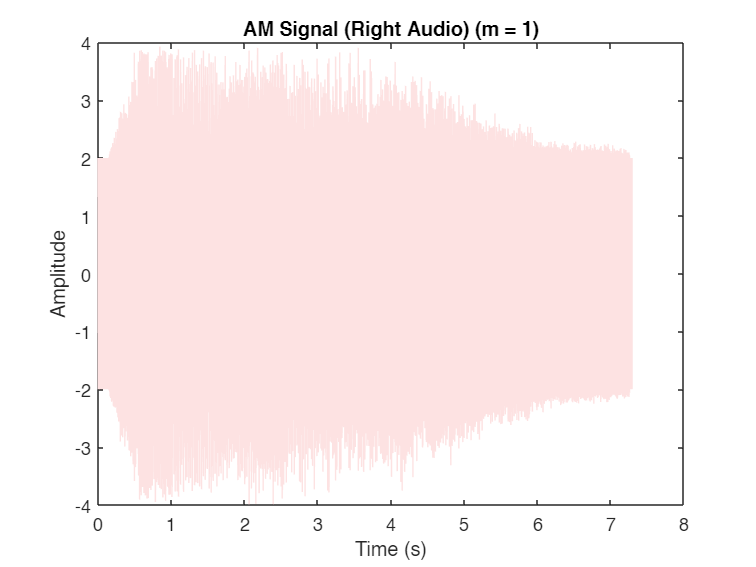

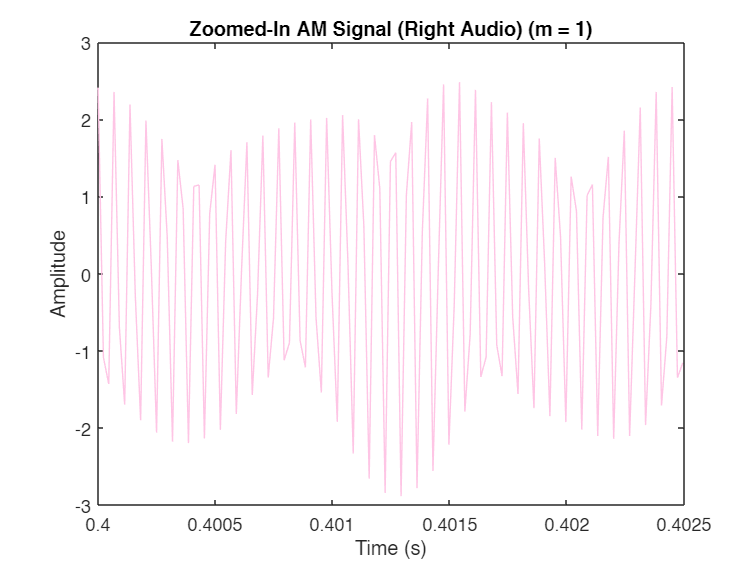

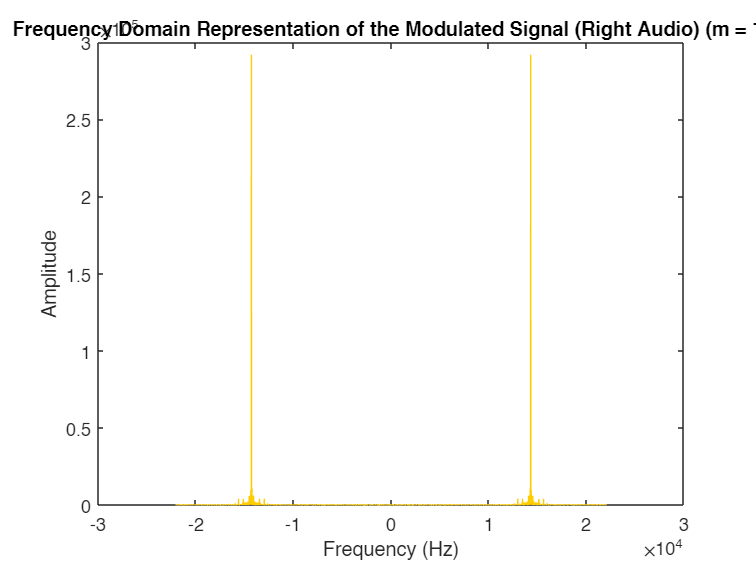

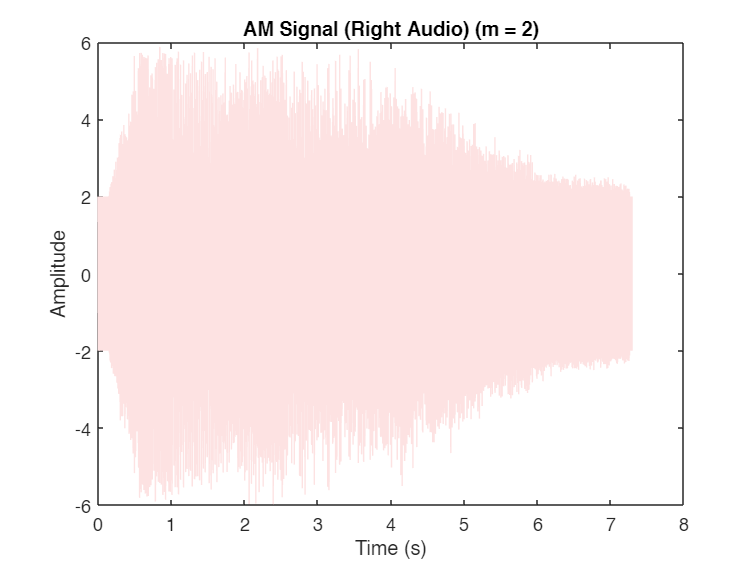

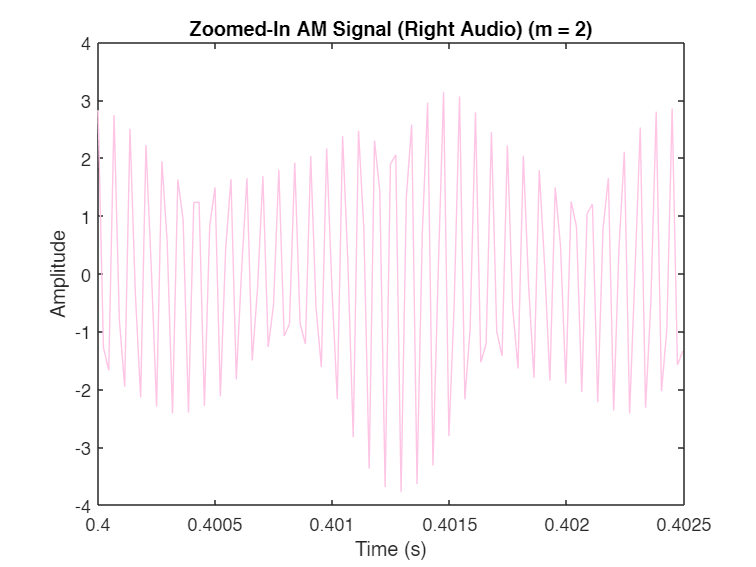

% Modulating right audio signal
r = reshape(r, size(c)); % Reshaping signal to match the shape of time vector

for i = 1:length(modulationIndices)
    % Generate the modulated signal with amplitude modulation (AM)
    m = modulationIndices(i); % Modulation index
    y = (1 + m * r) .* c; % AM modulation: Use .* for element-wise multiplication
    
    % Plot the modulated signal in the time domain
    figure;
    plot(t, y, 'Color', '#fde2e2');
    title(['AM Signal (Right Audio) (m = ', num2str(m), ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the zoomed-in AM signal
    figure;
    plot(t(zoomIdx), y(zoomIdx),'Color', '#fec5e5');
    title(['Zoomed-In AM Signal (Right Audio) (m = ', num2str(m), ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot the modulated signal in the frequency domain
    Y = fft(y);
    f = (-length(Y)/2:length(Y)/2 - 1) * fs / length(Y);
    
    figure;
    plot(f, abs(fftshift(Y)), 'Color', '#ffcc00');
    title(['Frequency Domain Representation of the Modulated Signal (Right Audio) (m = ', num2str(m), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
end